# Canonical Polyadic Decomposition exercise

## 1. Introduction

### 1.1 Goal

The goal of this exercise is to get familiar with the canonical polyadic decomposition (CPD) in practice, by implementing an algorithm to compute it (alternating least squares - ALS) and applying it on a synthetic data problem. 

### 1.2 Instructions

Your tasks will be to:

- Fill out the missing pieces of code in this file,

- Complete some of the functions inside the 'utils' folder,

- Answer the open-ended questions in this file.

#### Files needed for this exercise

- `*assignment_2_exercise_1.mlx           `- MATLAB live script that steps you through the CPD exercise 

- `*utils/cpd_als_3d.m                    `- Function that computes the CPD of a 3rd order tensor using the ALS algorithm

- `*utils/cpd_als_Nd.m                    `- Function that computes the CPD of a tensor of any order using the ALS algorithm (*bonus question*)

- `given/hidden_publish_results.p `                - Hidden function that will publish your filled in `*.m` files and `*.mlx` file into a single `.pdf` file

- `given/hidden_khatri_rao.p              `- Hidden function that calculates the Khatri-Rao product of two or more matrices (*implemented in assignment 1*)

- `given/hidden_mode_n_matricization.p    `- Hidden function that performs the unfolding (matricization) of a tensor of any order in any mode (*implemented in assignment 1*)

- `given/hidden_check_cpd_als.p           `- Hidden function that checks whether your implementations for `cpd_als_3d.m` and `cpd_als_Nd.m` are correct

- `given/hidden_cpd_als_3d.m              `- Hidden function that implements the CPD of a 3rd order tensor using the ALS algorithm. If you cannot implement `cpd_als_3d.m` correctly, you may use this function to proceed with the rest of the questions, or for debugging purposes.

- `given/hidden_cpd_als_Nd.m              `- Hidden function that implements the CPD of a tensor of any order using the ALS algorithm. You may use this function for debugging purposes.

- `data/3d_rank3_data.mat                 `- Synthetic data of a 3rd order tensor 

- `data/4d_rank5_data.mat                 `- Synthetic data of a 4th order tensor (*bonus question*)

****indicates files you will need to complete***

**Note**: all hidden functions follow the syntax of the corresponding functions in the previous assignment(s). For the syntax of `hidden_cpd_als_3d.m`, please check the preamble in `cpd_als_3d.m`.

You can refer to the course book ([1] Section 3.2) or [this paper](https://epubs.siam.org/doi/10.1137/07070111X) ([2] Section 3) and [this paper](https://ieeexplore.ieee.org/document/7891546) ([3] Sections III-IV) for implementing the required algorithms. Note that `hidden_mode_n_matricization.p` uses the convention of [1] and [2] for tensor unfolding and your algorithms should use the same convention. The convention for tensor unfolding in [3] is different, therefore the algorithm updates in the paper will look slightly different.

### **1.3 How to get full points**

- Hand in the homework on time. Late submissions are not taken into account and will be awarded 0 points.

- You should only submit a *.pdf file and the corresponding *.mlx file (see Submission below).

- ***.zip files and *.m files are not accepted, will not be graded and will be awarded 0 points**.

- All your answers and code should be visible in the *.pdf and the *.mlx files. If code lines exceed the page margin, make sure you break the lines in the *.mlx file.

- You are allowed to use your code and results from Assignment 1. 

- Make sure the output of your own functions and your plots are shown in the .pdf file.

- Write the explanation only where indicated and in text-form. Explanations given as comments in the code will not count towards the points awarded for the exercise. Nevertheless, we encourage you to follow good coding practice and use meaningful comments in the code. 

### **1.4 Submission**

- Run this *.mlx file including all your code and comments. 

- Uncomment and run the code block in Section 9 of this .mlx file.

- Confirm that the created file "assignment_2_exercise_2_submission.pdf" includes all your code and comments in the .mlx file and your implementation of the .m files you worked on.

- Upload the *.pdf file and this *.mlx file to Brightspace.

- *In case the above does not work*, please copy the content of your completed .m files at the bottom of this *.mlx file and subsequently go to Live Editor -> Export -> Export to .pdf. In this case, again, upload both the *.pdf file and this *.mlx file to Brightspace.

## 2. Canonical Polyadic Decomposition

A *polyadic decomposition* (PD) represents an $N$-th order tensor $\mathcal{X} \in \mathbb{R}^{I_1 \times I_2 \times \cdots \times I_N}$ as a linear combination of rank-1 tensors in the form


$$\mathbf{\underline{X}} = \sum_{r=1}^{R} c _r \: \mathbf{b}_r^{(1)} \: \circ \: \mathbf{b}_r^{(2)} \: \circ \: \cdots \: \circ \: \mathbf{b}_r^{(N)},$$


where $\mathbf{b}_r^{(n)} \in \mathbb{R}^{I_n \times 1}$ are vectors for $r = 1, \dots, R$ and $n = 1, \dots, N$ and the symbol $ \circ$ denotes the outer product operation. 

The *tensor rank* is defined as the smallest value of $R$ for which the above equation holds exactly. The PD of minimum rank is called *canonical polyadic decomposition* (CPD) and is a useful tool in signal separation applications. 

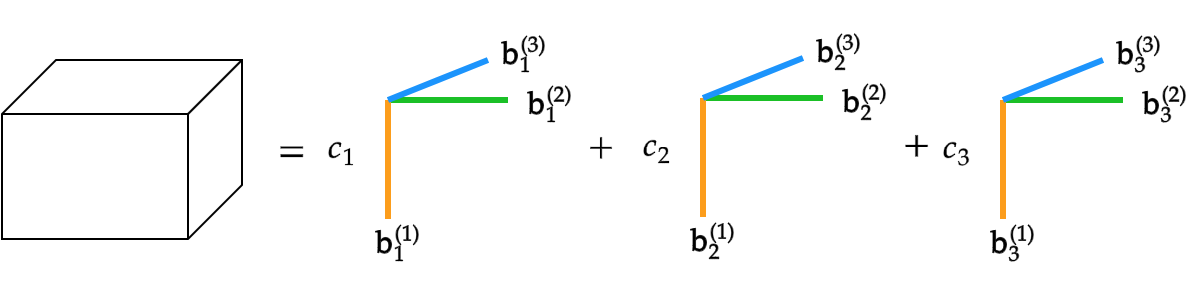

Schematic of the (exact) CPD for a 3-rd order tensor of rank 3.

The $N$ *factor matrices *$\textbf{B}^{(n)} $ contain the concatenation of the corresponding vectors, i.e. $\textbf{B}^{(n)} = [\mathbf{b}_1^{(n)} \: \mathbf{b}_2^{(n)} \: \dots \: \mathbf{b}_r^{(n)} ] \in \mathbb{R}^{I_n \times R}$. The columns of the factor matrices $\textbf{B}^{(n)} $ are called *signatures*. 

In the above formulation, it is assumed that the signatures $\mathbf{b}_r^{(n)}$, $i = 1, \dots, N$, are normalized to unit $l_2$-norm and all necessary coefficients are absorbed into the weights $c_r$. Normalizing the signatures is not mandatory, in general, but it can be useful to facilitate the inspection of the factor matrices.

The CPD can also be expressed as a multilinear product with a diagonal core tensor. Thus, we can write 


$$\mathbf{\underline{X}} = \mathbf{\underline{C}} \: \times_1 
\: \textbf{B}^{(1)} \: \times_2 \: \textbf{B}^{(2)} \: \cdots \: \times_N \: \textbf{B}^{(N)} \\ \quad = [\![  \mathbf{\underline{C}}; \textbf{B}^{(1)},  \textbf{B}^{(2)}, \dots, \textbf{B}^{(N)} ]\!],$$


where $\mathbf{\underline{C}}= \text{diag}_N(c_1, c_2, \dots, c_R)$ is the $N$-th order diagonal core tensor containing all weights $\lambda _r 
$ and $\times_n$ denotes the n-mode matrix-tensor product. 

The matrix form of the CPD can be obtained as:


$$\textbf{X}_{(n)} = \textbf{B}^{(n)} \textbf{C} \left( \textbf{B}^{(N)} \odot \cdots \odot \textbf{B}^{(n+1)} 
    \odot \textbf{B}^{(n-1)} \odot \cdots \odot \textbf{B}^{(1)} \right) ^T,$$


where $\textbf{X}_{(n)}$ is the tensor unfolding in the $n$-th mode, $\odot$ stands for the (column-wise) Khatri-Rao product and $\textbf{C} = \text{diag}(c_1, c_2, \dots, c_R)$.  

## 3. Load synthetic data

To start the exercise, click into the section below and then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables, the `close` command to close all figures and** i**t will add the 'utils', 'data' and 'given' folders to your current path.

clear; 
close all;
addpath(genpath('utils')); 
addpath(genpath('data')); 
addpath(genpath('given')); 

A 3-rd order synthetic data tensor $\mathbf{\underline{T}}$ of size 10x10x10 was built from the factor matrices $\mathbf{U}^{(1)}$,$\mathbf{U}^{(2)}$,$\mathbf{U}^{(3)}$, as


$$\underline{\textbf{{T}}} = \sum_{r=1}^{3} \mathbf{u}_r^{(1)} \: \circ \: \mathbf{u}_r^{(2)} \: \circ \: \mathbf{u}_r^{(3)},$$


where $\textbf{U}^{(n)} = [\mathbf{u}_1^{(n)} \: \mathbf{u}_2^{(n)} \: \mathbf{u}_3^{(n)} ] \in \mathbb{R}^{10 \times 3}$, $n = 1, 2, 3$. In this problem, the factor matrices have 3 columns, therefore, the generated tensor is of rank 3. Note that the signatures in the given factor matrices are not normalized to unit norm.

The factor matrices $\textbf{U}^{(n)}
$ are stored in a 1x3 cell array `U` in `3d_rank3_data.mat`; each cell corresponds to one factor matrix. The elements in the factor matrices were randomly generated from the uniform distribution $U(0, 1)$. 

In this exercise, you will code an algorithm to compute the CPD of tensor `T` and compare the estimated signatures with the true signatures.

To start with, in the following lines the data is loaded and the factor matrices, as well as the generated tensor, are stored in variables `U` and `T`, respectively. Additionally, two initialization points for the CPD algorithm are saved in variables `init1` and `init1`.

% Load data
data    = load('3d_rank3_data');
U       = data.U;     % Factor matrices
T       = data.T;     % Tensor to decompose
init1   = data.init1;   % One initialization point
init2   = data.init2;   % Another initialization point
clear data

## 4. Compute the CPD

### 4.1 Instructions

The problem of computing a CP decomposition for a given rank $R$ can be formulated as the optimization problem


$$\min_{\mathbf{\underline{\hat{T}}}} \|  \mathbf{\underline{T}} -  \mathbf{\underline{\hat{T}}} \| _F^2,$$


where


$$\mathbf{\underline{\hat{T}}} =\sum_{r=1}^{R} c_r  \: \mathbf{b}_r^{(1)} \: \circ \: \mathbf{b}_r^{(2)} \: \circ \: \mathbf{b}_r^{(3)} =  [\![ \mathbf{\underline{C}}; \textbf{B}^{(1)},  \textbf{B}^{(2)}, \textbf{B}^{(3)} ]\!].$$


You will be filling in the function `cpd_als_3d.m` by computing the CPD using the alternating least squares (ALS) algorithm, which is explained in [1-3]. The ALS algorithm consecutively fixes all but one factor matrices and optimizes for the remaining one; this procedure is repeated until some convergence criterion is satisfied. At each step, having fixed all but one matrix, the problem reduces to a linear least-squares problem.

Function inputs

The function `cpd_als_3d.m `accepts at least three inputs: the tensor to be decomposed (`T`), the rank of the decomposition (`R`) and some algorithm options (`options`). The latter is a structure containing the stopping criteria, which in this case are

- The threshold for the relative error of the decomposition `th_relerr` and

- The maximum number of interations `maxiter`. 

The function includes an optional argument: the initialization points for the factor matrices (all 3 initial points are then combined in one cell).

**Note 1: **The relative error of the decomposition is defined here as $\frac{\| \mathbf{\underline{T}} -  \mathbf{\underline{\hat{T}}} \|_F}{\| \mathbf{\underline{T}} \|_F}$, where $\mathbf{\underline{T}}$ is the original tensor, $\mathbf{\underline{\hat{T}}}$ is the reconstructed tensor as defined above and $\| \cdot\|_F$ denotes the Frobenius norm.

**Note 2: **In general, in ALS, one is free to define the order in which the factor matrices will be updated. In your implementation for this exercise, make sure that you are updating the factor matrices in this order: mode-1, mode-2, mode-3. The comments provided in `cpd_als_3d.m` will guide you in this.

**Note 3: **It is possible to use other stopping criteria for the algorithm, e.g. thresholding on the difference in the objective function value achieved in two consecutive iterations, relative to the initial value. **In this exercise, we will only use thresholding on the relative error as defined above and a maximum number of iterations.**

Outputs

The outputs of `cpd_als_3d.m` are the estimated factor matrices (`B1`, `B2` and `B3`), the vector (`c`) containing the weights $c_r$, as well as a structure `output`, which contains the number of iterations the algorithm ran for (`numiter`) and the relative error of the decomposition (`relerr`) achieved in all iterations, as defined in Note 1 above.

### 4.2 Code

We know that the tensor was generated with a rank equal to 3 so we can set the rank of the decomposition to 3. A reasonable choice for the maximum number of iterations for a simple problem like this is low (e.g. 300). For this noiseless case, we can expect to be able to achieve a very small error, so we set the threshold to$10^{-6}$. These values are defined in the code below:

R = 3;
options.maxiter = 300; 
options.th_relerr = 1e-6;

You should now fill in the code in `cpd_als_3d.m`. Afterwards, run the code block below to calculate the CPD using the given initialization and inspect the relative error achieved and the number of iterations that were used. 

**Hint: **Using this initialization, your algorithm should converge to a relative error smaller than$10^{-6}$ in fewer than 300 iterations.

**Debugging tip 1:** A plot of the evolution of the relative error per iteration can be an indication as to whether your algorithm is coded correctly.

**Debugging tip 2: **The code below will also call a provided test function `hidden_check_cpd_als.p` that will give you the actual relative error that your decomposition achieves. This should be equal to the relative error you calculated.

[B1, B2, B3, c, output] = cpd_als_3d(T, R, options, init1);
disp(['The algorithm stopped after # iterations: ' num2str(output.numiter)])

% Plot the relative error per iteration
figure; 
semilogy(output.relerr)
grid on
xlabel('Iteration number')
ylabel('Relative error $\frac{\| T-T_{dec} \|_F}{\| T\|_F}$','interpreter','latex');
title('Relative error of the decomposition')

**Question**

This question is on general coding practices: if no tensor data was provided, how would you generally verify that your CPD implementation is correct? You can answer in words, or include code below.

*Your answer goes here...*

*Your code goes here...*

% Optional code
% Code regarding testing the CPD implementation
% 

To check whether your implementation is correct, you can run the following code block that uses the given test function `hidden_check_cpd_als.p`

hidden_check_cpd_als(T, R, options, init1);

### 4.3 Results 

Now it is time to inspect the results of the decomposition: you will compare the estimated factor matrices `A`, `B`, `C` with the true factor matrices in `U`. Note that in CPD the order of the factors and the magnitude of the individual signatures are estimated ambiguously. 

One way to evaluate the result is to cross-correlate all columns of the estimated factor matrices with all columns of the corresponding true factor matrices.

**Note**: the function `corr.m` that is used below is part of the [Statistics and Machine Learning Toolbox](https://nl.mathworks.com/help/stats/index.html?s_tid=CRUX_lftnav). You will need to install it (available via TU Delft) to use the code block below.

*You are free to use another way to compare the true and the estimated factor matrices, if you prefer*.

disp('Correlation between true and estimated factor matrices: ')
disp('for B1: '); disp(round(corr(B1, U{1}), 3))
disp('for B2: '); disp(round(corr(B2, U{2}), 3)) 
disp('for B3: '); disp(round(corr(B3, U{3}), 3)) 

**Question**

What does the result show about the estimation of the factor matrices using the CPD? Please give specifics remarks given the correlation results above.

*Your answer goes here...*

*Your code goes here...*

% Optional code
% Code regarding the evaluation of the decomposition
% 


relerr =     0.1689    0.1340    0.1285    0.1236    0.1189    0.1137    0.1079    0.1020    0.0967    0.0929    0.0904    0.0889    0.0879    0.0873    0.0868    0.0864    0.0860    0.0856    0.0853    0.0850    0.0846    0.0843    0.0839    0.0835    0.0830    0.0825    0.0820    0.0814    0.0807    0.0798    0.0788    0.0776    0.0761    0.0741    0.0716    0.0681    0.0633    0.0568    0.0481    0.0380    0.0288    0.0225    0.0189    0.0168    0.0155    0.0144    0.0136    0.0128    0.0121    0.0115


## 5. Uniqueness

**Question**

Is the CPD decomposition for this particular tensor *essentially unique* [3]? Please answer below and support your claim using code.

*Your answer goes here...*

*Your code goes here...*

[s11, s12, s13, c1, out] = cpd_als_3d(T, 3, options);

The algorithm stopped after # iterations: 285


[s21, s22, s23, c2, out] = cpd_als_3d(T, 3, options);

rec_1 = s11 * khatri_rao(s13, s12)';
rec_2 = s21 * khatri_rao(s23, s22)';

frob_norm(rec_1 - rec_2)

## 6. Experiment with the CPD ALS algorithm

### 6.1 Algorithm options

Now you will experiment with different algorithm options (i.e. rank, maximum number of iterations, threshold on relative error). You can use the following coding block for this.

You are asked to make observations on the outcome (in terms of correlation of the true and estimated factors or any other way you prefer), as a function of the parameters. The specific questions to be answered can be found below.

Feel free to include code (e.g. parameter values, initialization and results) or plots under each question to support your claims.

**Note**: the initialization point is not given now; thus, the algorithm will start from a random point every time. In your added code blocks, you can choose to fix it to a specific parameter but do not use the `init2` provided parameter. 

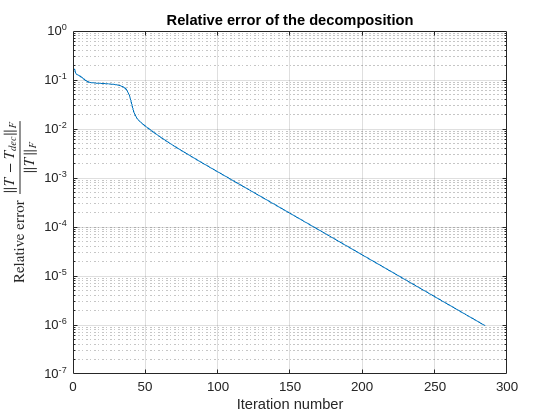

% Set parameters
R =3% CPD rank

relerr = 0.9869

relerr =     0.1689    0.1340    0.1285    0.1236    0.1189    0.1137    0.1079    0.1020    0.0967    0.0929    0.0904    0.0889    0.0879    0.0873    0.0868    0.0864    0.0860    0.0856    0.0853    0.0850    0.0846    0.0843    0.0839    0.0835    0.0830    0.0825    0.0820    0.0814    0.0807    0.0798    0.0788    0.0776    0.0761    0.0741    0.0716    0.0681    0.0633    0.0568    0.0481    0.0380    0.0288    0.0225    0.0189    0.0168    0.0155    0.0144    0.0136    0.0128    0.0121    0.0115


Your calculated relative error of the decomposition: 9.6275e-07
The relative error of the actual decomposition: 9.6275e-07


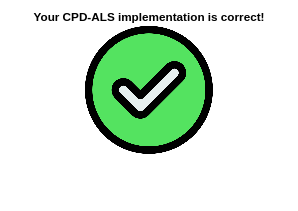

options.maxiter = 300; % maximum number of iterations
options.th_relerr = 1e-6 % threshold on relative error

% Compute the CPD
[B1, B2, B3, c, output] = cpd_als_3d(T, R, options);

% Results
disp(['Relative error of the decomposition: ' num2str(output.relerr(end))])
disp(['The algorithm stopped after # iterations: ' num2str(output.numiter)])
% 
disp('Correlation between true and estimated factor matrices: ');
disp('for B1: '); disp(round(corr(B1, U{1}), 3))
disp('for B2: '); disp(round(corr(B2, U{2}), 3)) 

disp('for B3: '); disp(round(corr(B3, U{3}), 3))
%
% Plot the relative error per iteration
figure; 
semilogy(output.relerr)
grid on
xlabel('Iteration number')

Correlation between true and estimated factor matrices: 


ylabel('Relative error $\frac{\| T-T_{dec} \|_F}{\| T\|_F}$','interpreter','latex');

for B1: 


corr requires one of the following:
  Econometrics Toolbox
  Statistics and Machine Learning Toolbox

title('Relative error of the decomposition')

**Question**

The ALS algorithm requires the (expected) rank of the tensor as an input. 

a) What happens if you underestimate the rank? 

b) What happens if you overestimate the rank? 

c) How would you choose the rank in practice, for a tensor with unknown rank?

*Your answer goes here...*

*Your code goes here...*

% Code regarding rank choice
% 


**Question**

a) What is the effect of increasing or decreasing the maximum number of iterations? 

b) What is the effect of increasing or decreasing the threshold for the relative error?

Please answer the above questions considering this noiseless case, but also thinking about a general noisy case.

Please include an example plot (along with the related code and parameters), where you can see that the algorithm has converged to a solution.

*Your answer goes here...*

*Your code goes here...*

% Code regarding maximum number of iterations
%
% Code regarding relative error threshold
% 

### 6.2 Algorithm initialization and update order

ALS-CPD is an iterative optimization-based method and it is not guaranteed to converge to a global minimum. The final solution can be heavily dependent on the initialization and the chosen algorithm options. That means that, even if the CPD of a tensor is essentially unique in theory, we cannot be sure that we obtain the theoretical result in practice using ALS.

Your task is to inspect this behavior. The code below will run the `cpd_als_3d.m` function with another given initialization point.   

% Set parameters
R = 3;
options.maxiter = 300; 
options.th_relerr = 1e-6;
%
% Compute the CPD
[B1, B2, B3, c, output] = cpd_als_3d(T, R, options, init2);

% Results
disp(['Relative error of the decomposition: ' num2str(output.relerr(end))])
disp(['The algorithm stopped after # iterations: ' num2str(output.numiter)])
%
disp('Correlation between true and estimated factor matrices: ');
disp('for A: '); disp(round(corr(B1, U{1}), 3))
disp('for B: '); disp(round(corr(B2, U{2}), 3)) 

relerr =     0.1491    0.1086    0.0956    0.0871    0.0811    0.0767    0.0733    0.0705    0.0679    0.0651    0.0618    0.0577    0.0521    0.0444    0.0346    0.0248    0.0181    0.0148    0.0132    0.0122    0.0113    0.0106    0.0100    0.0094    0.0089    0.0084    0.0079    0.0075    0.0071    0.0068    0.0064    0.0061    0.0058    0.0056    0.0053    0.0051    0.0048    0.0046    0.0044    0.0042    0.0040    0.0039    0.0037    0.0035    0.0034    0.0033    0.0031    0.0030    0.0029    0.0028


disp('for C: '); disp(round(corr(B3, U{3}), 3))

relerr =     0.1950    0.1395    0.1292    0.1178    0.1079    0.1023    0.0990    0.0961    0.0929    0.0892    0.0846    0.0785    0.0704    0.0602    0.0502    0.0425    0.0367    0.0320    0.0282    0.0253    0.0231    0.0214    0.0199    0.0187    0.0176    0.0166    0.0156    0.0147    0.0139    0.0131    0.0123    0.0116    0.0110    0.0103    0.0097    0.0092    0.0086    0.0081    0.0077    0.0072    0.0068    0.0064    0.0061    0.0057    0.0054    0.0051    0.0048    0.0046    0.0043    0.0041


%
% Plot the relative error per iteration
figure; 
semilogy(output.relerr)
grid on

ans = 2.9248e-05

xlabel('Iteration number')
ylabel('Relative error $\frac{\| T-T_{dec} \|_F}{\| T\|_F}$','interpreter','latex');
title('Relative error of the decomposition')

**Question**

What are your observations regarding the effect of the initialization on the performance of the algorithm? You are encouraged to play with the number of iterations and/or the threshold. Please include the chosen values in your answer.

*Your answer goes here...*

*Your code goes here...*

% Optional
% Code regarding the initialization point
% 

**Question**

Does the order in which the factor matrices are updated affect the result of the algorithm? Please use code to support your claim. You should check this without altering the `cpd_als_3d.m` function. 

**Hint**: To answer this question you choose fix the initialization.

*Your answer goes here...*

*Your code goes here...*

% Code regarding the order of updating the factor matrices


## **7. Future application**

**Question (10 points)**

Given all your answers in section 6, how would you apply the ALS-CPD algorithm in practice to obtain the CPD of a tensor, in noiseless and noisy problems?

*Your answer goes here...*

## 8. Bonus - CPD for higher order tensors

As a bonus (and non-mandatory) task, you are asked to implement an ALS-CPD algorithm that will be able to handle higher order ($\geq 3$) tensors.

A 4th order synthetic data tensor $\mathbf{\underline{T}}$ of size 7x11x4x9 was built from the factor matrices $\mathbf{U}_1$,$\mathbf{U}_2$,$\mathbf{U}_3$,$\mathbf{U}_4$. The factor matrices are stored in a 1x4 cell array `U`; each cell corresponds to one factor matrix. The elements in the factor matrices were randomly generated from the Gaussian distribution $N(1, 0.5)$. Note that the signatures in the given factor matrices are not normalized to unit norm, thus we can write


$$\mathbf{\underline{T}} = \sum_{r=1}^{5} \mathbf{u}_r^{(1)} \: \circ \: \mathbf{u}_r^{(2)} \: \circ \: \mathbf{u}_r^{(3)} \: \circ \: \mathbf{u}_r^{(4)}.$$


In this synthetic problem, the factor matrices have 5 columns, therefore, the generated tensor is of rank 5.

Your task is to fill in the function `cpd_als_Nd.m.`

Running the following code block will load the relevant data.

% Clear previous data
clear 
% Load data
data = load('4d_rank5_data');
U = data.U;
T = data.T;
init1 = data.init1;
clear data

Running the following code block will set some algorithm options.

% Set algorithm options
R = 5;
options.maxiter = 300; 
options.th_relerr = 1e-6;

To check whether your implementation is correct, you can run the following code block that uses the given test function `hidden_check_cpd_als.p`

hidden_check_cpd_als(T, R, options, init1);

After filling in the function `cpd_als_Nd.m`, the results of the decomposition can be collected running the following code block.

% Collect results
[V, c, output] = cpd_als_Nd(T, R, options, init1);
disp(['The algorithm stopped after # iterations: ' num2str(output.numiter)])

% Plot the relative error per iteration
figure; 
semilogy(output.relerr)
grid on
xlabel('Iteration number')
ylabel('Relative error $\frac{\| T-T_{dec} \|_F}{\| T\|_F}$','interpreter','latex');
title('Relative error of the decomposition')

% Inspect the factor matrices
disp('Correlation between true and estimated factor matrices: ');
disp('for U{1}: '); disp(round(corr(V{1}, U{1}), 3))
disp('for U{2}: '); disp(round(corr(V{2}, U{2}), 3)) 
disp('for U{3}: '); disp(round(corr(V{3}, U{3}), 3))
disp('for U{4}: '); disp(round(corr(V{4}, U{4}), 3))

## 9. Prepare results for submission

Uncomment the following code lines and run the code to prepare the .pdf file for submission. (Running this code block might take a while.)

% hidden_publish_results('assignment_2_exercise_1_submission.pdf', ...
% 'assignment_2_exercise_1.mlx', 'utils', {'cpd_als_3d.m', 'cpd_als_Nd.m'})

## References

[1] Andrzej Cichocki et al. "Tensor Networks for Dimensionality Reduction and Large-scale Optimization: Part 1 Low-Rank Tensor Decompositions", In: Foundations and Trends® in Machine Learning: Vol. 9: No. 4-5 (2016), pp 249-429. http://dx.doi.org/10.1561/2200000059

[2] Tamara G. Kolda, Brett W. Bader. “Tensor Decompositions and Applications”. In: SIAM Rev. 51.3 (Aug. 2009), 455–500. issn: 0036-1445. doi: 10.1137/07070111X. url: https: //doi.org/10.1137/07070111X.

[3] Nicholas D. Sidiropoulos et al. “Tensor Decomposition for Signal Processing and Machine Learning”. In: IEEE Transactions on Signal Processing 65.13 (2017), pp. 3551–3582. doi:10.1109/TSP.2017.2690524.